clear all;

% Step 1: Read the audio file
[audioData, fs] = audioread('Ih.wav');
sample_duration = 1/2; % duration in seconds for 2 Hz resolution
start_sample = 1000; % starting sample index
end_sample = start_sample + sample_duration * fs - 1; % ending sample index

audio_sample = audioData(start_sample:end_sample);


% Step 2: Generate the 1000Hz sine wave
T_s = length(audio_sample) / fs; % duration of the audio sample in seconds
[time_vector, sine_wave] = generate_sinusoid(1, 1000, 0, fs, T_s);

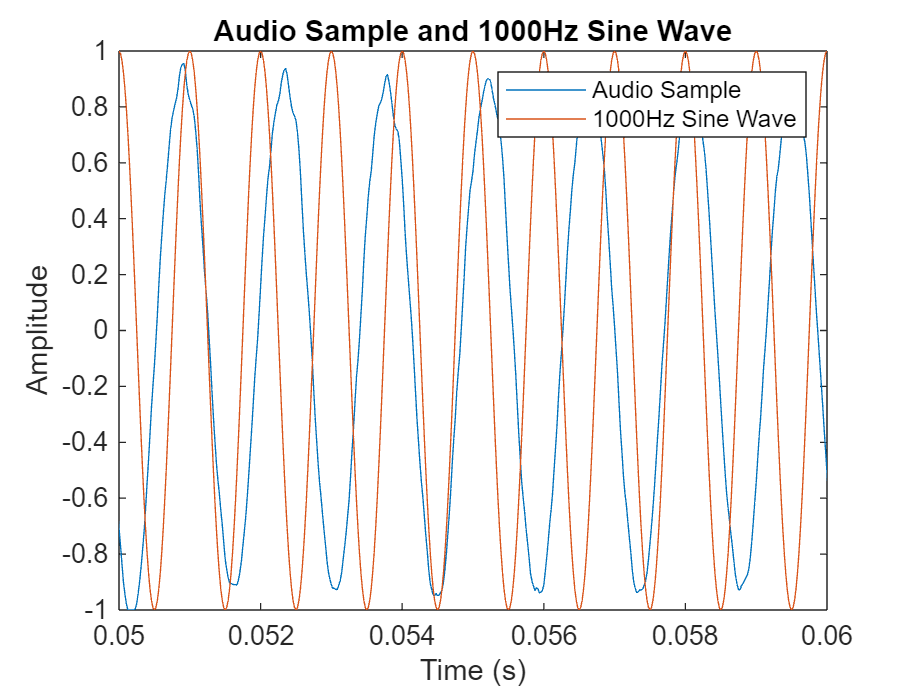


% Step 3: Plot both signals
figure;
plot((0:length(audio_sample)-1)/fs, audio_sample);
hold on;
plot(time_vector, sine_wave);
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Sample and 1000Hz Sine Wave');
legend('Audio Sample', '1000Hz Sine Wave');
xlim([0.05 0.06]); % Set x-axis limits here
hold off;


% Function to generate a sinusoid
function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    time_vector = 0:1/fs:T_s-1/fs;    % our time vector
    signal = a*cos(2*pi*f*time_vector + phi);
end
